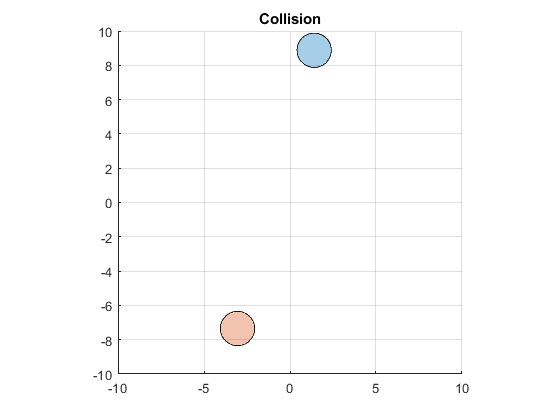

close all
clear c1 c2
c1 = circle;
c2 = circle;
x = [1 0];
y = [0 1];
[v1,b1,v2,b2] = generateRandomV(3);
for i = linspace(0,3,50)
    c1.polygon = translate(polyshape(c1.xdata,c1.ydata),v1*i+b1);
    c2.polygon = translate(polyshape(c1.xdata,c1.ydata),v2*i+b2);
    if detectCollision(c1,c2) == true
        title('Collision')
        break
    end
    renderer([c1.polygon,c2.polygon])
end

function collision = detectCollision(p1,p2)
    if class(p1) == "circle" && class(p2) == "circle"
        %% pasar a la funcion colision circle vs cirle
        collision = circleVScircle(p1,p2);
    elseif class(p1) == "circle" || class(p2) == "circle"
        %% pasar a la funcion poligono vs circle
        disp('circulo vs poligono')
    else
        % pasar a la funcion poligono vs poligonoS
        disp('poligono vs poligono')
    end
end

